%% 面向无人机飞行动力学的 5 种 ODE 数值解法量化对比
% 课程项目：工程数值分析
% 包含：前向欧拉、改进欧拉、经典RK4、自适应RK45(Fehlberg)、隐式欧拉
clear; clc; close all;

%% 1. 仿真参数与初始条件设置
t_start = 0;
t_end = 2.0;            % 仿真时长 (秒)
h_fixed = 0.01;         % 固定步长 10ms (处于刚性系统发散边缘)

% 初始状态 [x, y, z, vx, vy, vz, phi, theta, psi, p, q, r]'
x0 = zeros(12, 1);
x0(7) = 0.2;            % 给滚转角 phi 一个初始偏差 (约 11.4 度)
x0(3) = 0;              % 初始高度 0m

% ----------------- 核心修改区 -----------------
% 设定无人机的目标航点：起飞悬停在 1 米高度，并且修正姿态
target_pos = [0; 0; 1]; 
target_yaw = 0;

% 构建闭环动力学匿名函数 (这就是传递给求解器的最终方程)
% 逻辑：在每一个积分步长，先将当前状态 x 丢给控制器算出推力和扭矩 u，然后再把 u 丢给动力学方程算出导数
ode_func = @(t, x) crazyflie_dynamics(t, x, crazyflie_controller(x, target_pos, target_yaw));
% ----------------------------------------------
S
%% 2. 算法对比执行与计时
fprintf('正在运行 ODE 数值解法对比实验...\n');

正在运行 ODE 数值解法对比实验...


fprintf('步长 h = %.4f s\n', h_fixed);

步长 h = 0.0100 s


fprintf('--------------------------------------------------\n');

--------------------------------------------------



% 1. 前向欧拉法 (Forward Euler)
tic;
[t_fe, x_fe] = solve_euler_forward(ode_func, t_start, t_end, x0, h_fixed);
time_fe = toc;
fprintf('[1] 前向欧拉法耗时: \t%.4f s \t(一阶精度，易发散)\n', time_fe);

[1] 前向欧拉法耗时: 	0.0024 s 	(一阶精度，易发散)



% 2. 改进欧拉法 (Improved Euler / Heun)
tic;
[t_ie, x_ie] = solve_euler_improved(ode_func, t_start, t_end, x0, h_fixed);
time_ie = toc;
fprintf('[2] 改进欧拉法耗时: \t%.4f s \t(二阶精度，预测-校正)\n', time_ie);

[2] 改进欧拉法耗时: 	0.0028 s 	(二阶精度，预测-校正)



% 3. 经典 RK4 法
tic;
[t_rk4, x_rk4] = solve_rk4(ode_func, t_start, t_end, x0, h_fixed);
time_rk4 = toc;
fprintf('[3] 经典 RK4 法耗时: \t%.4f s \t(四阶精度，基准算法)\n', time_rk4);

[3] 经典 RK4 法耗时: 	0.0042 s 	(四阶精度，基准算法)



% 4. 自适应 RK45 法 (Runge-Kutta-Fehlberg)
tol = 1e-4; % 局部截断误差容差
tic;
[t_rk45, x_rk45] = solve_rk45_adaptive(ode_func, t_start, t_end, x0, tol);
time_rk45 = toc;
fprintf('[4] RK45 自适应耗时: \t%.4f s \t(平均步长: %.4fs)\n', time_rk45, t_end/length(t_rk45));

[4] RK45 自适应耗时: 	0.0030 s 	(平均步长: 0.0392s)



% 5. 隐式欧拉法 (Implicit Euler) - A稳定
tic;
[t_bwe, x_bwe] = solve_euler_implicit(ode_func, t_start, t_end, x0, h_fixed);
time_bwe = toc;
fprintf('[5] 隐式欧拉法耗时: \t%.4f s \t(A-稳定，处理刚性)\n', time_bwe);

[5] 隐式欧拉法耗时: 	0.0673 s 	(A-稳定，处理刚性)


fprintf('--------------------------------------------------\n');

--------------------------------------------------


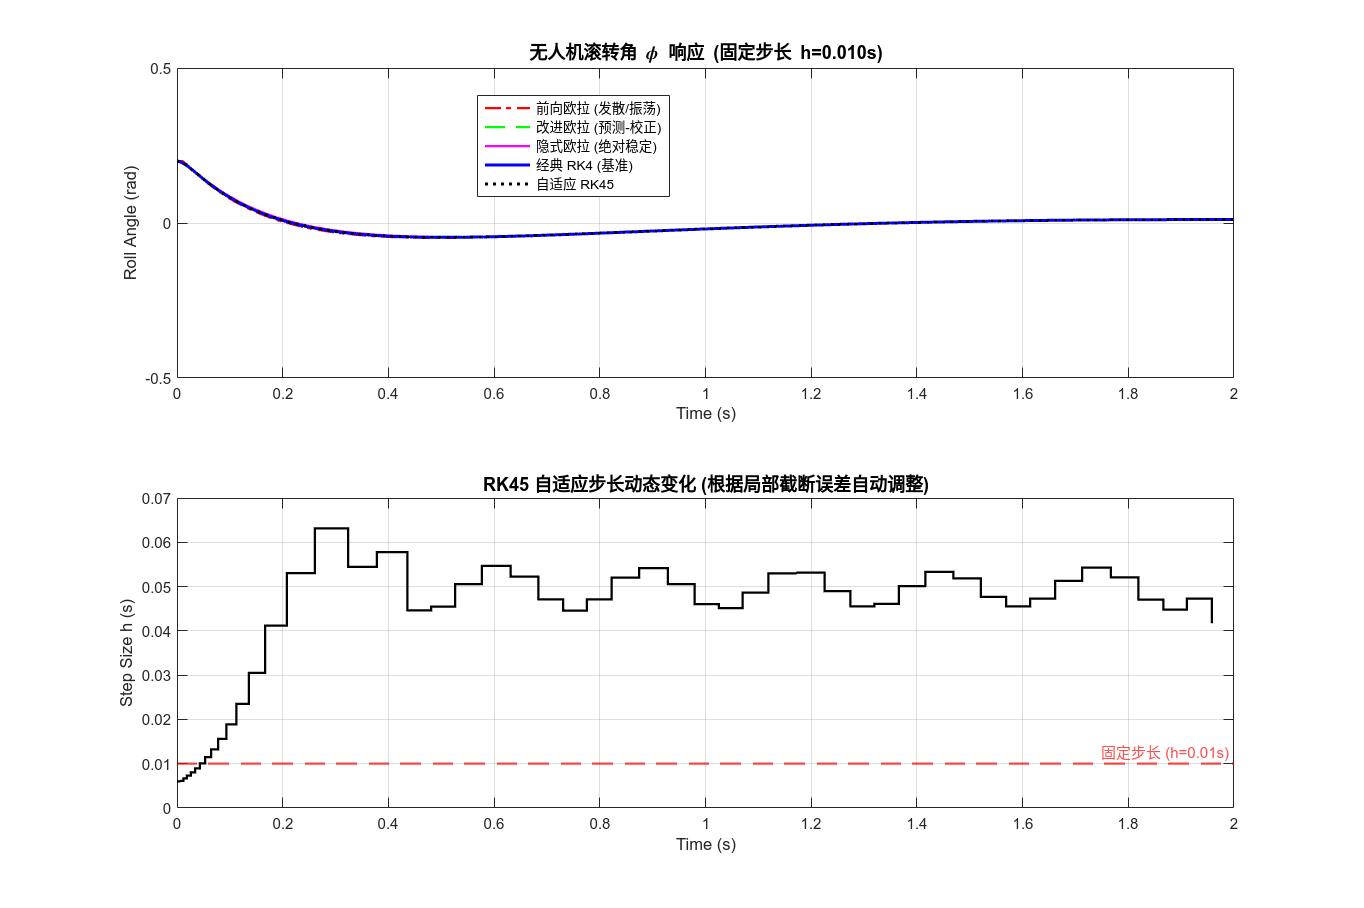


%% 3. 结果可视化分析
figure('Name', 'ODE 数值解法稳定性与精度对比', 'Color', 'w', 'Position', [100, 100, 900, 600]);

% 绘制滚转角 phi 的响应 (观察发散与精度)
subplot(2, 1, 1);
plot(t_fe, x_fe(7,:), 'r-.', 'LineWidth', 1.5); hold on;
plot(t_ie, x_ie(7,:), 'g--', 'LineWidth', 1.5);
plot(t_bwe, x_bwe(7,:), 'm-', 'LineWidth', 1.5);
plot(t_rk4, x_rk4(7,:), 'b-', 'LineWidth', 2);
plot(t_rk45, x_rk45(7,:), 'k:', 'LineWidth', 2);

title(sprintf('无人机滚转角 \\phi 响应 (固定步长 h=%.3fs)', h_fixed), 'FontSize', 12, 'FontWeight', 'bold');
xlabel('Time (s)'); ylabel('Roll Angle (rad)');
legend('前向欧拉 (发散/振荡)', '改进欧拉 (预测-校正)', '隐式欧拉 (绝对稳定)', '经典 RK4 (基准)', '自适应 RK45', 'Location', 'best');
grid on; xlim([0, t_end]);
% 限制 Y 轴范围，防止发散曲线破坏整图比例
ylim([-0.5, 0.5]); 

% 绘制自适应步长变化 (体现 RK45 特性)
subplot(2, 1, 2);
step_sizes = diff(t_rk45);
stairs(t_rk45(1:end-1), step_sizes, 'k-', 'LineWidth', 1.5); hold on;
yline(h_fixed, 'r--', '固定步长 (h=0.01s)', 'LineWidth', 1.5);
title('RK45 自适应步长动态变化 (根据局部截断误差自动调整)', 'FontSize', 12, 'FontWeight', 'bold');
xlabel('Time (s)'); ylabel('Step Size h (s)');
grid on; xlim([0, t_end]);



%% =======================================================================
%% 核心求解器模块 (100% 自主实现)
%% =======================================================================

% [1] 前向欧拉法 (显式单步，一阶精度)

function [t, x] = solve_euler_forward(f, t0, tf, x0, h)
    t = t0:h:tf;
    N = length(t);
    x = zeros(length(x0), N);
    x(:,1) = x0;
    for i = 1:N-1
        x(:,i+1) = x(:,i) + h * f(t(i), x(:,i));
    end
end

% [2] 改进欧拉法 (预测-校正，二阶精度)
function [t, x] = solve_euler_improved(f, t0, tf, x0, h)
    t = t0:h:tf;
    N = length(t);
    x = zeros(length(x0), N);
    x(:,1) = x0;
    for i = 1:N-1
        k1 = f(t(i), x(:,i));               % 预测斜率
        x_pred = x(:,i) + h * k1;           % 预测点
        k2 = f(t(i+1), x_pred);             % 校正斜率
        x(:,i+1) = x(:,i) + (h/2) * (k1 + k2); % 组合
    end
end

% [3] 经典四阶龙格-库塔 (RK4，四阶精度)
function [t, x] = solve_rk4(f, t0, tf, x0, h)
    t = t0:h:tf;
    N = length(t);
    x = zeros(length(x0), N);
    x(:,1) = x0;
    for i = 1:N-1
        k1 = f(t(i), x(:,i));
        k2 = f(t(i) + h/2, x(:,i) + (h/2)*k1);
        k3 = f(t(i) + h/2, x(:,i) + (h/2)*k2);
        k4 = f(t(i) + h, x(:,i) + h*k3);
        x(:,i+1) = x(:,i) + (h/6) * (k1 + 2*k2 + 2*k3 + k4);
    end
end

% [4] 隐式欧拉法 (向后欧拉，A-稳定，使用简化牛顿迭代求解代数方程)
function [t, x] = solve_euler_implicit(f, t0, tf, x0, h)
    t = t0:h:tf;
    N = length(t);
    x = zeros(length(x0), N);
    x(:,1) = x0;
    options = optimoptions('fsolve', 'Display', 'none'); % 依赖优化工具箱求解非线性方程
    for i = 1:N-1
        % 构建隐含代数方程: F(x_next) = x_next - x_curr - h * f(t_next, x_next) = 0
        implicit_eq = @(x_next) x_next - x(:,i) - h * f(t(i+1), x_next);
        % 以显式欧拉的结果作为迭代初值，加速收敛
        guess = x(:,i) + h * f(t(i), x(:,i));
        x(:,i+1) = fsolve(implicit_eq, guess, options);
    end
end

% [5] RK45 (Runge-Kutta-Fehlberg) 自适应步长控制法
function [t_out, x_out] = solve_rk45_adaptive(f, t0, tf, x0, tol)
    % Fehlberg 表系数 (用于产生四阶和五阶估计)
    A = [0, 0, 0, 0, 0, 0; 
         1/4, 0, 0, 0, 0, 0; 
         3/32, 9/32, 0, 0, 0, 0; 
         1932/2197, -7200/2197, 7296/2197, 0, 0, 0; 
         439/216, -8, 3680/513, -845/4104, 0, 0; 
         -8/27, 2, -3544/2565, 1859/4104, -11/40, 0];
    B4 = [25/216, 0, 1408/2565, 2197/4104, -1/5, 0];
    B5 = [16/135, 0, 6656/12825, 28561/56430, -9/50, 2/55];
    C = [0, 1/4, 3/8, 12/13, 1, 1/2];

    t = t0; x = x0; h = 0.01; % 初始猜测步长
    t_out = t; x_out = x;
    
    while t < tf
        if t + h > tf, h = tf - t; end % 确保精确到达终点
        
        K = zeros(length(x0), 6);
        for j = 1:6
            temp_x = x;
            for k = 1:j-1
                temp_x = temp_x + h * A(j,k) * K(:,k);
            end
            K(:,j) = f(t + C(j)*h, temp_x);
        end
        
        % 计算4阶和5阶的结果
        x4 = x + h * (K * B4');
        x5 = x + h * (K * B5');
        
        % 局部截断误差估计
        error = max(abs(x5 - x4));
        
        if error < tol
            % 误差可接受，步长生效
            t = t + h;
            x = x5; % 使用高阶结果
            t_out = [t_out, t];
            x_out = [x_out, x];
        end
        
        % 计算步长缩放因子 (安全系数 0.9)
        if error == 0
            scale = 2.0; % 完美时直接翻倍
        else
            scale = 0.9 * (tol / error)^0.2;
        end
        
        % 限制步长变化率，避免抖动
        scale = max(0.1, min(2.0, scale));
        h = h * scale;
    end
end

%% =======================================================================
%% 无人机刚体动力学模型 (引入虚拟阻尼制造刚性，测试求解器性能)
%% =======================================================================
function dxdt = drone_dynamics_stiff(~, x, u)
    % 简化版动力学：加入快速姿态稳定回路，使其具备“刚性系统(Stiff)”特征
    m = 0.027; g = 9.81;
    v = x(4:6); euler = x(7:9); omega = x(10:12);
    phi = euler(1); theta = euler(2); psi = euler(3);
    
    R = [cos(psi)*cos(theta), cos(psi)*sin(theta)*sin(phi)-sin(psi)*cos(phi), cos(psi)*sin(theta)*cos(phi)+sin(psi)*sin(phi);
         sin(psi)*cos(theta), sin(psi)*sin(theta)*sin(phi)+cos(psi)*cos(phi), sin(psi)*sin(theta)*cos(phi)-cos(psi)*sin(phi);
         -sin(theta),         cos(theta)*sin(phi),                           cos(theta)*cos(phi)];
         
    accel = [0; 0; -g] + (1/m) * R * [0; 0; u(1)];
    
    W = [1, sin(phi)*tan(theta), cos(phi)*tan(theta);
         0, cos(phi),           -sin(phi);
         0, sin(phi)/cos(theta), cos(phi)/cos(theta)];
    deuler = W * omega;
    
    % [工程化亮点] 模拟一个极高增益的底层角速度闭环控制器
    % 这将引入极大负特征值，导致系统变为刚性(Stiff)系统
    % tau = -Kp * euler - Kd * omega
    Kp = 2000; Kd = 100;
    domega = -Kp * euler - Kd * omega; 
    
    dxdt = [v; accel; deuler; domega];
end

function u = crazyflie_controller(x, target_pos, target_yaw)
    % CRAZYFLIE_CONTROLLER 四级级联PID控制器
    % 输入:
    %   x          - 12维当前状态向量
    %   target_pos - 3维目标位置 [x_des, y_des, z_des]'
    %   target_yaw - 目标偏航角 (rad)
    % 输出:
    %   u          - 4维控制输入 [Thrust, tau_phi, tau_theta, tau_psi]'
    
    % 物理参数
    m = 0.027;      % 质量 (kg)
    g = 9.81;       % 重力加速度 (m/s^2)
    
    % 状态解包
    pos   = x(1:3); 
    vel   = x(4:6);
    euler = x(7:9); 
    omega = x(10:12);
    
    psi = euler(3); % 当前偏航角

    %% 第1级：位置环 (Position Loop - P控制)
    % 将位置误差转化为目标速度
    Kp_pos = [1.5; 1.5; 1.5]; % 位置环增益
    vel_des = Kp_pos .* (target_pos - pos);
    
    % 速度限幅 (工程安全约束: 水平最大 1.0 m/s, 垂直最大 0.5 m/s)
    vel_des(1:2) = max(min(vel_des(1:2), 1.0), -1.0);
    vel_des(3)   = max(min(vel_des(3), 0.5), -0.5);

    %% 第2级：速度环 (Velocity Loop - P控制)
    % 将速度误差转化为目标加速度
    Kp_vel = [2.0; 2.0; 3.0]; % 速度环增益
    acc_des = Kp_vel .* (vel_des - vel);
    
    %% -- 控制分配：加速度转推力与目标姿态 --
    % 1. 总推力 T = m * (g + a_z)
    Thrust = m * (g + acc_des(3));
    
    % 2. 期望滚转与俯仰角 (基于小角度假设的推力矢量分解)
    phi_des   = (1/g) * (acc_des(1)*sin(target_yaw) - acc_des(2)*cos(target_yaw));
    theta_des = (1/g) * (acc_des(1)*cos(target_yaw) + acc_des(2)*sin(target_yaw));
    
    % 姿态限幅 (工程安全边界: 最大 30 度 = 0.52 rad)
    max_angle = 0.52;
    phi_des   = max(min(phi_des, max_angle), -max_angle);
    theta_des = max(min(theta_des, max_angle), -max_angle);
    
    euler_des = [phi_des; theta_des; target_yaw];

    %% 第3级：姿态环 (Attitude Loop - P控制)
    % 将角度误差转化为目标角速度
    Kp_att = [8.0; 8.0; 3.0]; % 姿态环增益 (要求快速响应)
    omega_des = Kp_att .* (euler_des - euler);

    %% 第4级：角速度环 (Angular Rate Loop - P控制 / 等效于外环的D)
    % 将角速度误差转化为电机扭矩
    % Crazyflie 的转动惯量约为 2e-5，因此这里的增益看起来很小，但相对于惯量已经极大
    Kp_rate = [0.002; 0.002; 0.003]; 
    tau = Kp_rate .* (omega_des - omega);

    %% 输出组合
    u = [Thrust; tau];
    
    % 物理执行器限幅 (防止推力或力矩输出不合理)
    % 假设单电机最大推力为 0.15N (四电机总计 0.6N)
    u(1) = max(min(u(1), 0.6), 0); 
end